根据 ImageJ RoiSet 配准图像

此函数接受 ImageJ RoiSet 和晃动图输入，根据RoiSet中圈定的特征点位置进行匹配，得到变换矩阵，然后配准输入图像，并返回所用的变换矩阵。

ROI包括固定ROI和晃动ROI。每个晃动ROI应当对应一个晃动图文件，且具有相同的Z层数。固定ROI要么只有一个被所有晃动图共用，要么为每个晃动ROI匹配一个对应的固定ROI。将计算出一个变换矩阵，使得晃动ROI的中心点变换到对应固定ROI的位置，并用同样的矩阵变换晃动图文件，生成ROI配准图文件。

为此，晃动ROI文件中包含的ROI个数和位置顺序，必须与对应固定ROI文件中包含的ROI个数和位置顺序一一对应。不对应不一定会出错，而可能会生成完全错误扭曲的配准图和变换矩阵。Z层数可以容许一定程度上的不同，固定ROI可以比晃动ROI具有更多的Z层数，将对前几个Z层匹配，后续Z层将会忽略；但是，晃动图文件和ROI的Z层数必须相等。

## 语法

## 示例

错误ROI示例。ROI序号与图上位置不匹配，将导致配准结果异常。

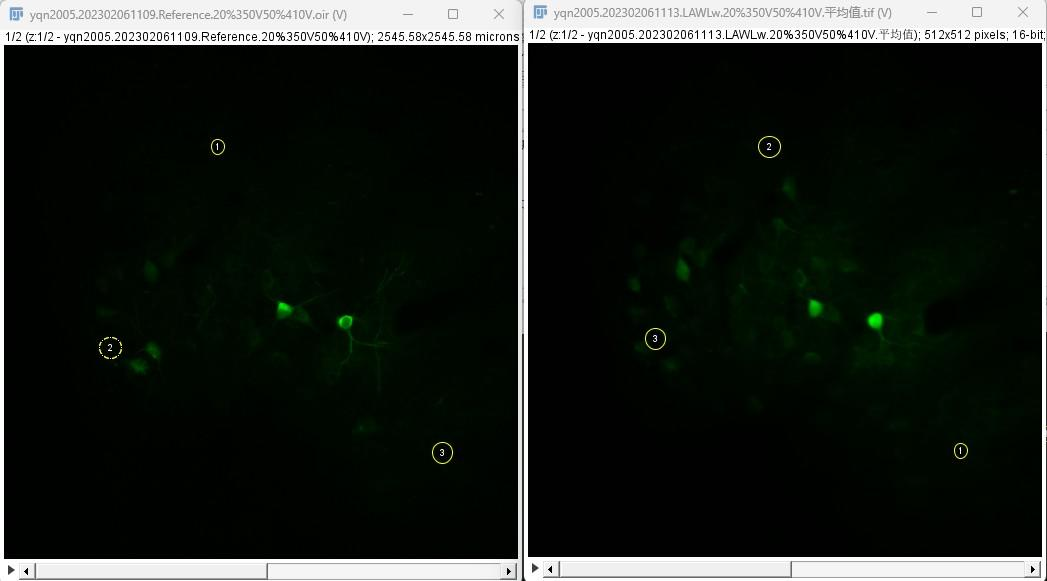

正确ROI示例

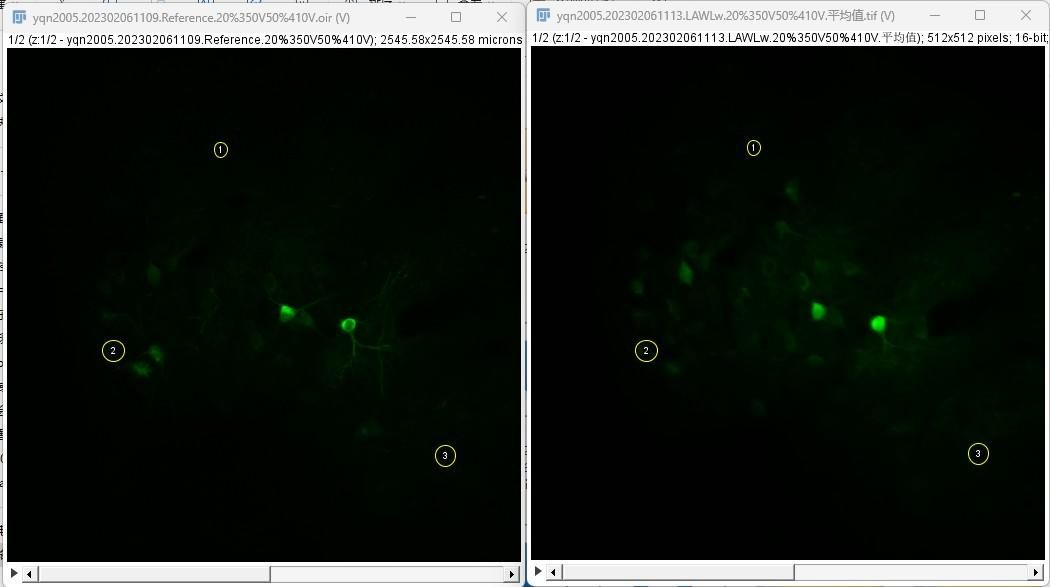

所有Z层都必须全部按顺序严格对应匹配

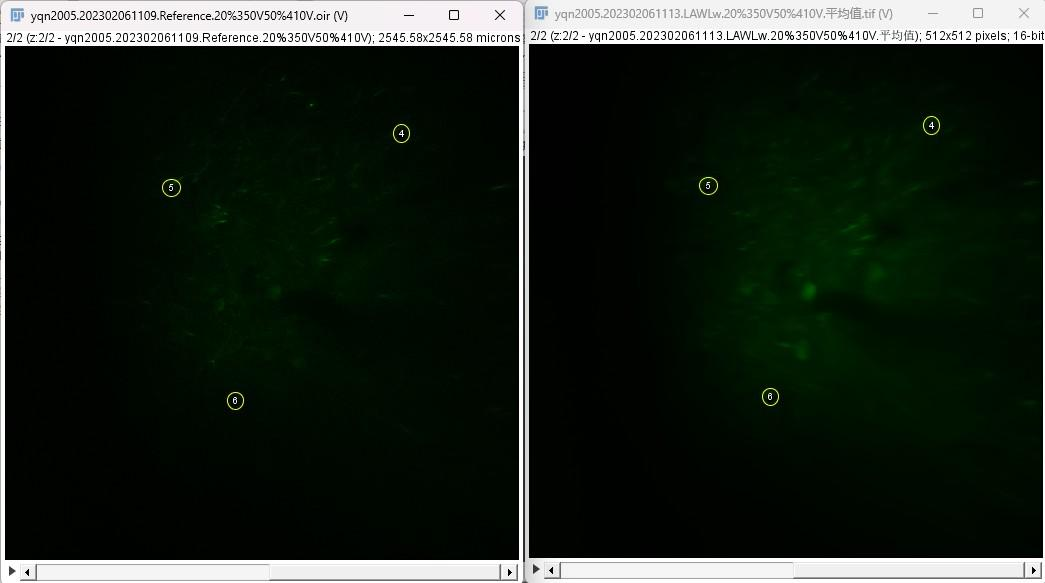

## 输入参数

PathTable(:,2:3)table，要试配的晃动图路径表，一行一个晃动图。包含以下列：

- MovingImage(:,1)string，必需，要试配的晃动平均图的路径

- MovingRoi(:,1)string，必需，要试配的晃动RoiSet的路径

- FixedRoi(:,1)string，可选，要试配的固定RoiSet的路径

FixedRoi(1,1)string，固定图的ROI路径。如果PathTable中未指定FixedRoi列，则必须指定本参数；否则不允许指定本参数。

OutputDirectory(1,1)string="."，输出目录

## 返回值

TransMatrix(:,1)cell，变换矩阵。每个元胞对应一个晃动图，元胞内是(1,:)affinetform2d，对应每个Z层。

**See also** [UniExp.BatchOirRegisterTiff](matlab:doc UniExp.BatchOirRegisterTiff) [UniExp.OirSampleMean](matlab:doc UniExp.OirSampleMean)

function TransMatrix = RoiRegister(PathTable,varargin)
ManyFixed=any(PathTable.Properties.VariableNames=="FixedRoi");
OutputDirectory='.';
for V=1:numel(varargin)
	if isfolder(varargin{V})
		OutputDirectory=varargin{V};
	elseif ~ManyFixed&&isfile(varargin{V})
		FixedRoi=RoiCenters(varargin{V});
	else
		UniExp.Exceptions.Unexpected_argument_type.Throw;
	end
end
NumMovings=height(PathTable);
TransMatrix=cell(NumMovings,1);
for M=1:NumMovings
	MovingRoi=RoiCenters(PathTable.MovingRoi(M));
	MovingImage=PathTable.MovingImage(M);
	[~,Filename,Extension]=fileparts(MovingImage);
	switch Extension
		case ".oir"
			Reader=Image5D.OirReader(MovingImage);
			Writer=Image5D.OmeTiffRWer.Create(fullfile(OutputDirectory,Filename+".ROI配准.tif"),Image5D.PixelType.UINT16,Reader.SizeX,Reader.SizeY,Reader.ChannelColors,Reader.SizeZ,Reader.SizeT,Image5D.DimensionOrder.XYCZT);
		case ".tif"
			Reader=Image5D.OmeTiffRWer.OpenRead(MovingImage);
			Writer=Image5D.OmeTiffRWer.Create(fullfile(OutputDirectory,Filename+".ROI配准.tif"),Reader.ImageDescription);
		otherwise
			UniExp.Exceptions.The_MovingSamples_extension_must_be_oir_or_tif.Throw(sprintf('第%u个MovingSamples扩展名不正确',M));
	end
	if Reader.SizeT>1
		UniExp.Exceptions.Moving_image_is_a_video.Throw(sprintf('第%u个晃动图是视频，请选择单帧图像文件',M));
	end
	MovingImage=Reader.ReadPixels;
	RefObj=imref2d(size(MovingImage));
	[~,~,SizeZ]=size(MovingImage);
	if SizeZ~=numel(MovingRoi)
		UniExp.Exceptions.ZLayers_of_the_moving_ROI_and_file_do_not_match.Throw(sprintf('第%u个晃动图和ROI的Z层数不同',M));
	end
	if ManyFixed
		FixedRoi=RoiCenters(PathTable.FixedRoi(M));
	end
	TM=cell(1,SizeZ);
	for Z=1:SizeZ
		if width(MovingRoi{Z})~=width(FixedRoi{Z})
			UniExp.Exceptions.Numbers_of_fixed_and_moving_ROIs_vary.Throw(sprintf('第%u个文件的第%u层，固定和晃动图ROI数目不同',M,Z));
		end
		TM{Z}=ImageProcessing.FixedPointTform2D(MovingRoi{Z},FixedRoi{Z});
		MovingImage(:,:,Z)=imwarp(MovingImage(:,:,Z),TM{Z},OutputView=RefObj);
	end
	Writer.WritePixels(MovingImage);
	TransMatrix{M}=[TM{:}];
end
end

function CxyZ=RoiCenters(Roi)
[Cxy,~,Zs]=UniExp.internal.ImageJRoiReadout(Roi);
%Zs可能只有2
[Groups,Zs]=findgroups(Zs);
%因为imwarp会颠倒XY，最方便的方法就是这里进行颠倒
CxyZ(Zs)=splitapply(@(CP){CP'},fliplr(Cxy),Groups);
end